# Geometric Transformation Matrices

the different types of changes in perspective: translation, scale, shear, rotation, and tilt. For 2D images, each of these transformations can be represented as a 3 by 3 numeric matrix whose elements follow a specific pattern. In this reading, you'll see the matrix patterns for each of the five types of transformations and how different matrix values result in different levels of perspective changes.

## Importing Original Image

First, read in this image of a stop sign and display it. All the transformations in this reading will be performed on this image, so it is helpful to remind yourself what the original image looks like first.

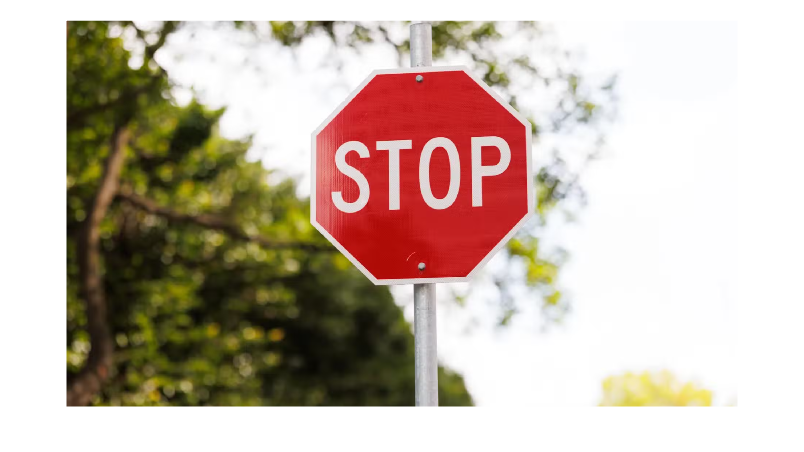

img = imread("stopSign.png");
imshow(img)

## Translation

For differences in translation, the transformation matrix takes the following form: 

$\pmatrix{1&0&tx \cr 0&1&ty \cr 0 & 0 & 1}$6

where $tx$ is the displacement along x axis and $ty$ is the displacement along y axis. Adjust the $tx$ and $ty$ values below to create the geometric transformation matrix and warp the initial image. Note that in this case, the displayed image does not look different, but the pixel values of the image itself have shifted according to the $tx$ and $ty$ values.

tx = 30;
ty = 93;
ATr = [1 0 tx;
       0 1 ty;
       0 0 1];
tformTr = affinetform2d(ATr);
warpedImgTr = imwarp(img,tformTr);
imshow(warpedImgTr)

## Rotation

For changes in rotation, the transformation matrix looks like this:


$$\pmatrix{cos(th)&-sin(th)&0 \cr
sin(th)&cos(th)&0\cr
0&0&1}$$


where $th$, or theta, is the angle of rotation. Adjust the slider below to see how different theta values affect the final result.

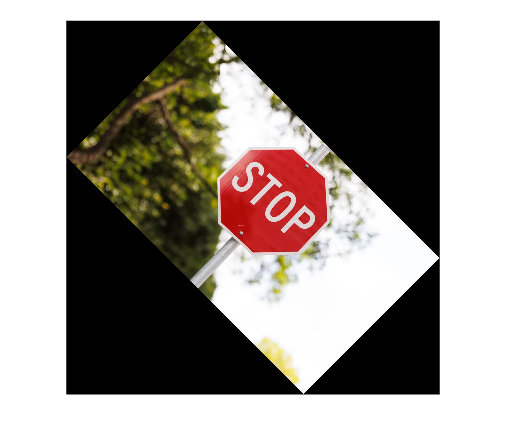

th =45;
ARo = [cosd(th) -sind(th) 0;
       sind(th) cosd(th)  0;
       0        0         1];
tformRo = affinetform2d(ARo);
warpedImgRo = imwarp(img,tformRo);
imshow(warpedImgRo)

## Scale

The transformation matrix for changes in scale takes the following form:


$$\pmatrix{sx&0&0\cr 0&sy&0\cr 0&0&1}$$


where $sx$ is the scale factor along x axis and $sy$ is the scale factor along y axis. Adjust the sliders below to see how the image can be scaled in both the x and y directions.

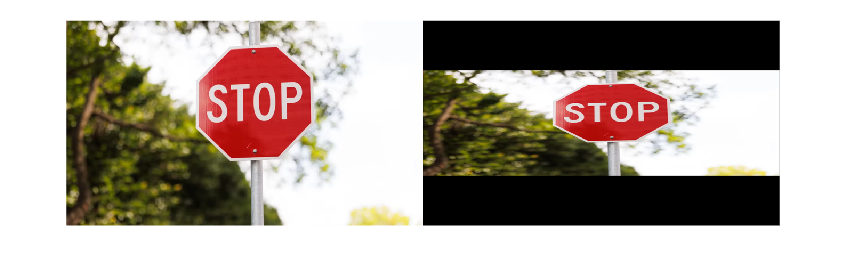

sx = 3.7;
sy = 1.9;
ASc = [sx 0  0;
       0  sy 0;
       0  0  1];
tformSc = affinetform2d(ASc);
warpedImgSc = imwarp(img,tformSc);
montage({img, warpedImgSc})

## Shear

For shear, the transformation matrix is as follows:


$$\pmatrix{1&shx&0\cr shy&1&0\cr 0&0&1}$$


where $shx$ is the shear factor in the x direction and $shy$ is the shear factor in the y direction. As you adjust the sliders below, notice how the image often looks dramatically different from the original, but the parallel lines are always maintained.

shx =1.6;
shy =2.8;
ASh = [1   shx 0;
       shy 1   0;
       0   0   1];
tformSh = affinetform2d(ASh);
warpedImgSh = imwarp(img,tformSh);
imshow(warpedImgSh)

## Tilt

The last transformation type is tilt, which can be represented in a matrix of this form:


$$\pmatrix{1&0&0\cr 0&1&0\cr E&F&1}$$


In a tilted image, a sense of depth is created by having parallel lines converge to a vanishing point. Here, $E$ and $F$ are both values that influence the vanishing point. 

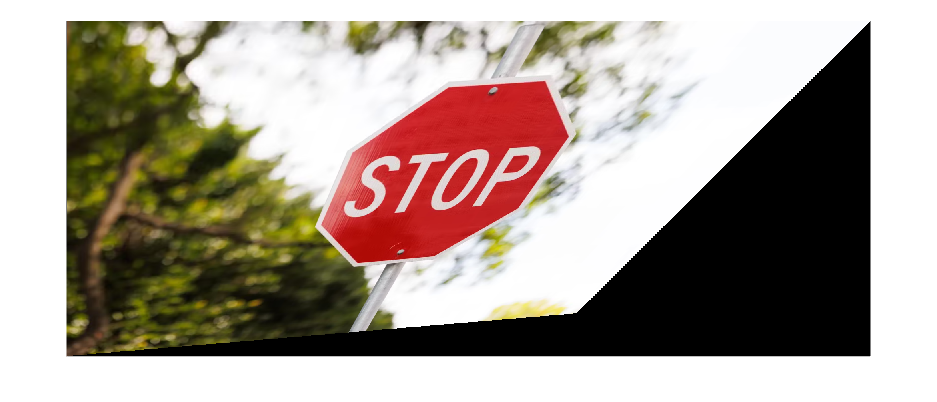

E =0.0008;
F =0.0003;
ATi = [1 0 0;
       0 1 0;
       E F 1];
tformTi = projtform2d(ATi);
warpedImgTi = imwarp(img,tformTi);
imshow(warpedImgTi)

## Combining Two Transformations

When you get to image stitching later in the course, you'll see how you can combine the effects of two types of transformations by multiplying their matrices. Below, you can see how changes in rotation and scale can be combined by multiplying their two matrices together and applying the result.

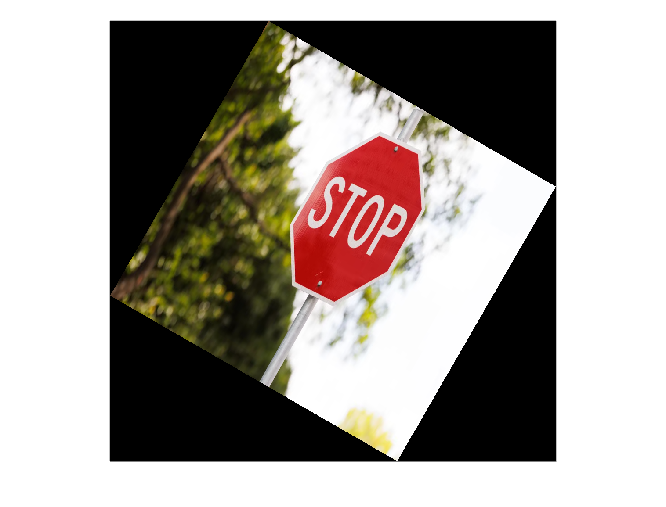

th =30;
A1 = [cosd(th) -sind(th) 0;
      sind(th) cosd(th)  0;
      0        0         1];
sx = 0.3;
sy = 0.5;
A2 = [sx 0  0;
      0  sy 0;
      0  0  1];
A = A1 * A2;
tform = affinetform2d(A);
warpedImg = imwarp(img,tform);
imshow(warpedImg)